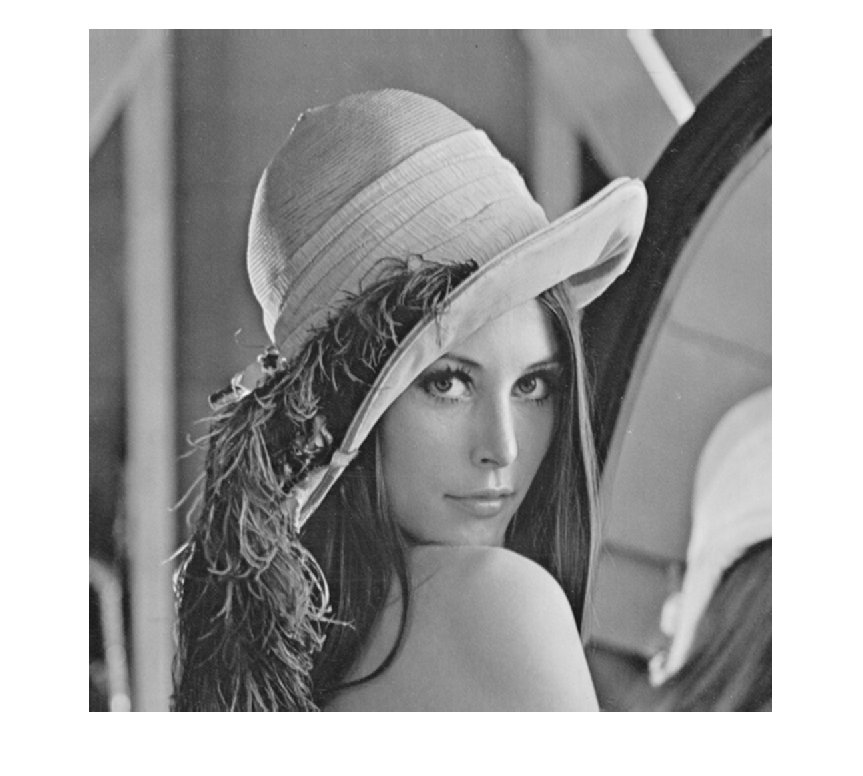

imagename=imread('lena.png');
imagename=rgb2gray(imagename);
scale=2;
bmn=bmn_bicubic(imagename,scale);
bmn=uint8(bmn);
imshow(bmn)

function [Bicube]=bmn_bicubic(imagename,scale)

Im=imagename; %Assign image variable name
k=scale; %Assign variable name to scale
a=-1.3; %Assign value to independent varaible a
[M,N]=size(Im); %Get size of image
Im=double(Im);
%INTERPOLATION WITH LEFT AND UP SHIFT
%calculate interpolation distances
S1=zeros(k,4); %Intitalise displacement vector
for i=0:k-1
S1(i+1,1)=abs(1+i/k);
S1(i+1,2)=abs(i/k);
S1(i+1,3)=abs(1-i/k);
S1(i+1,4)=abs(2-i/k);
end
%Calculate interpolation function
U1row=zeros(k,4);
for i=1:k
for j=1:4
if S1(i,j)<1
U1row(i,j)=(a+2).*(S1(i,j).^3)-(a+3).*(S1(i,j).^2)+1;
elseif 1<=S1(i,j)<2
U1row(i,j)=a.*(S1(i,j).^3)-(5*a).*(S1(i,j).^2)+...
(8*a).*S1(i,j)-(4*a);
else 
    U1row(i,j)=0;
end
end
end
U1col=U1row'; %Columns interpolation function
%Extend input image rows using symmetric padding
ROW1=Im(1,:); %Extract first row
ROWlast_1=Im(M-1,:); %Extract last but one row
ROWlast=Im(end,:); %Extract last row
Ipt1=[ROW1;Im;ROWlast;ROWlast_1]; %Extend rows in input image
%Interpolate rows
Wip1=zeros(k*M,N); %Initialise rows interpolated image
for i=1:M
j=k*(i-1);
Wip1(j+1:j+k,:)=U1row*Ipt1(i:i+3,:);
end
%Extend columns for image with extrapolated rows using symmetric padding
COL1=Wip1(:,1); %Extract first column
COLlast_1=Wip1(:,N-1); %Extract last but one column
COLlast=Wip1(:,end); %Extract last column
Ipt2=[COL1 Wip1 COLlast COLlast_1]; %Extend columns
%Interpolate columns
Wip2=zeros(k*M,k*N); %Initialise image with ext. colmns
for i=1:N
j=k*(i-1);
Wip2(:,j+1:j+k)=Ipt2(:,i:i+3)*U1col;
end
%INTERPOLATION WITH RIGHT AND DOWN SHIFT
%calculate interpolation distances
S2=zeros(k,4); %Intitalise displacement vector
for i=1:k
S2(i,1)=abs(2-(k-i)/k);
S2(i,2)=abs(1-(k-i)/k);
S2(i,3)=abs((k-i)/k);
S2(i,4)=abs(1+(k-i)/k);
end
%Calculate interpolation function 
U2row=zeros(k,4);
for i=1:k
for j=1:4
if S2(i,j)<1
U2row(i,j)=(a+2).*(S2(i,j).^3)-(a+3).*(S2(i,j).^2)+1;
elseif 1<=S2(i,j)<2
U2row(i,j)=a.*(S2(i,j).^3)-(5*a).*(S2(i,j).^2)+(8*a).*S2(i,j)-(4*a);
else 
    U2row(i,j)=0;
end
end
end
U2col=U2row'; %Columns interpolation function
%Extend input image columns using symmetric padding
COL1=Im(:,1); %Extract first column
COL2=Im(:,2); %Extract second column
COLlast=Im(:,end); %Extract last column
Ipt3=[COL2 COL1 Im COLlast]; %Extend columns
%interpolate columns
Wip3=zeros(M,k*N); %Initialise columns interpolated image
for i=1:N
j=k*(i-1);
Wip3(:,j+1:j+k)=Ipt3(:,i:i+3)*U2col;
end
%Extend rows for image with extrapolated rows using symmetric padding
ROW1=Wip3(1,:); %Extract first row
ROW2=Wip3(2,:); %Extract second row
ROWlast=Wip3(end,:); %Extract last row
Ipt4=[ROW2;ROW1;Wip3;ROWlast]; %Extend rows in input image
%Interpolate rows
Wip4=zeros(k*M,k*N); %Initialise image with ext. rows
for i=1:M
j=k*(i-1);
Wip4(j+1:j+k,:)=U2row*Ipt4(i:i+3,:);
end
%Average the two interpolations
Bicube=(Wip2+Wip4)./2;
%Truncate extrapolated data to within limits of input
L=min(min(Im)); %Minimum value of input data
U=max(max(Im)); %Maximum value of input data
for i=1:k*M
for j=1:k*N
if Bicube(i,j)<L
Bicube(i,j)=L; %Truncate low values to L
elseif Bicube(i,j)>U
Bicube(i,j)=U; %Truncate high values to U
end
end
end
end